clearvars;clc;

data_folder = '.\data\';
patient = 'ai6_micontinuous\';
files{1} = 'ai6.20180316.153104.offline.mi.mi_bhbf.gdf';
files{2} = 'ai6.20180316.154006.offline.mi.mi_bhbf.gdf';
files{3} = 'ai6.20180316.154811.offline.mi.mi_bhbf.gdf';
files{4} = 'ai6.20180316.160351.online.mi.mi_bhbf.ema.gdf';
files{5} = 'ai6.20180316.161026.online.mi.mi_bhbf.dynamic.gdf';
files{6} = 'ai6.20180417.164812.online.mi.mi_bhbf.ema.gdf';
files{7} = 'ai6.20180417.165259.online.mi.mi_bhbf.dynamic.gdf';
files{8} = 'ai6.20180529.151753.online.mi.mi_bhbf.ema.gdf';
files{9} = 'ai6.20180529.152240.online.mi.mi_bhbf.dynamic.gdf';
%mnemonic codes
code.fixation = 786;
code.cue_BH = 773;
code.cue_BF = 771;
code.cue_rest = 783;
code.feedback = 781;
modality.offline = 0;
modality.online = 1;
data_path = './data/';
%sub-band of frequencies of psd we are interested in
selected_frequences = (4:2:48)';
channel_labels  = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4', 'C3', 'C1', 'Cz', 'C2', 'C4', 'CP3', 'CP1', 'CPz', 'CP2', 'CP4'};
num_features = 3;
%load the weigths to select the features
feature_weights = load('features_filter.mat').features_filter';


## load EEG

EEG_data = cell(size(files));

for file = 1 : length(files)
    [s,h] = sload(fullfile(data_path, patient, files{file}));
    EEG_data{file}.signal = s;
    EEG_data{file}.header = h;
end


## convert EEG into PSD

PSD_data = cell(size(EEG_data));
original_frequences=nan;
for eeg_i = 1 : length(EEG_data)
    signal = EEG_data{eeg_i}.signal;
    header = EEG_data{eeg_i}.header;
    PSD_data{eeg_i} = psd_extraction(signal, header);
    %adding modality info
    if contains(files{eeg_i},"offline")
        PSD_data{eeg_i}.modality = modality.offline;
    elseif contains(files{eeg_i},"online")
        PSD_data{eeg_i}.modality = modality.online;
    else
        error(['Unknown modality for file: ' eeg_i]);
    end
    original_frequences = PSD_data{eeg_i}.frequences;
end

[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events


## concatenate files and label data

[PSD, EVENT, run_labels, modality_labels] = concatenatePSD(PSD_data);

num_windows  = size(PSD, 1);
[cue_type_labels, trial_labels] = labelData(EVENT, num_windows);

offline_data_index = (modality_labels == modality.offline);
online_data_index = (modality_labels == modality.online);
bf_bh_data_index = (cue_type_labels == code.cue_BH | cue_type_labels == code.cue_BF);


## log and sub-frequences extraction

PSD = log(PSD);
[PSD, frequences] = extractFrequences(PSD, original_frequences, selected_frequences);
    

## convert PSDs into dataset for the classifiers


classes = unique(cue_type_labels(bf_bh_data_index));
[X, selected_freq_chan_index , fisher_score_run] = psd2features(PSD, run_labels, cue_type_labels, classes, num_features ,feature_weights);

## compute mean fisher's score

mean_fisher_score = mean(fisher_score_run,3);

## filter mean fisher's score

filtered_mean_Fisher = mean_fisher_score .* feature_weights;

## generate map of selected features

features_mask = zeros(size(mean_fisher_score));

for k = 1 : length(selected_freq_chan_index)
    feature_index = selected_freq_chan_index{k};
    features_mask(feature_index(1), feature_index(2)) = 1;
end

## Visualization Fisher score

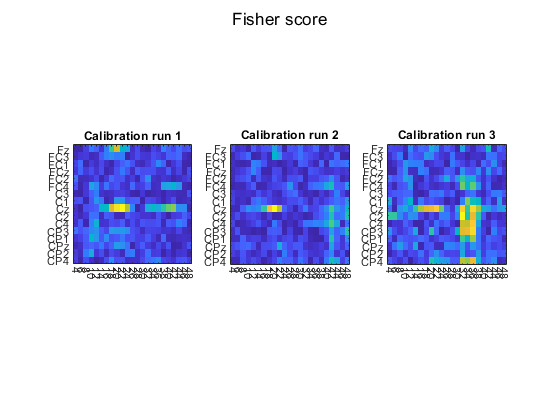

channelId  = 1:length(channel_labels);

NumRuns = length(EEG_data);
NumFreqs = length(frequences);
NumChans = length(channel_labels);
classId    = [773 771];
classLb    = {'both hands', 'both feet'};
nclasses   = length(classId);
modalityId = [0 1];
modalityLb = {'offline', 'online'};
OfflineRuns = [1 2 3];
climits = [];
handles = nan(NumRuns, 1);
fig1 = figure;

for rId = 1:length(OfflineRuns)
    subplot(1, 3, rId);
    imagesc(fisher_score_run(:, :, OfflineRuns(rId))');
    axis square;
    set(gca, 'XTick', 1:NumFreqs);
    set(gca, 'XTickLabel', frequences);
    set(gca, 'YTick', 1:NumChans);
    set(gca, 'YTickLabel', channel_labels);
    xtickangle(-90);
    
    title(['Calibration run ' num2str(OfflineRuns(rId))]);
    
    climits = cat(2, climits, get(gca, 'CLim'));
    handles(OfflineRuns(rId)) = gca;
end


sgtitle('Fisher score');

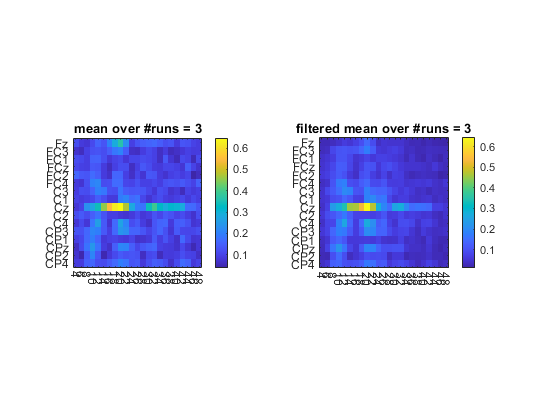

fig2=figure;
subplot(1,2,1);
imagesc(mean_fisher_score');
axis square;
set(gca, 'XTick', 1:NumFreqs);
set(gca, 'XTickLabel', frequences);
set(gca, 'YTick', 1:NumChans);
set(gca, 'YTickLabel', channel_labels);
xtickangle(-90);
colorbar;

title(['mean over #runs = ' num2str(OfflineRuns(rId))]);

subplot(1,2,2);
imagesc(filtered_mean_Fisher');
axis square;
set(gca, 'XTick', 1:NumFreqs);
set(gca, 'XTickLabel', frequences);
set(gca, 'YTick', 1:NumChans);
set(gca, 'YTickLabel', channel_labels);
xtickangle(-90);
colorbar;

title(['filtered mean over #runs = ' num2str(OfflineRuns(rId))]);

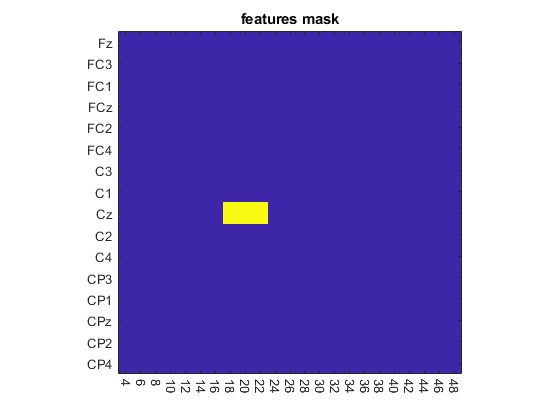



figure3=figure;
imagesc(features_mask');
axis square;
set(gca, 'XTick', 1:NumFreqs);
set(gca, 'XTickLabel', frequences);
set(gca, 'YTick', 1:NumChans);
set(gca, 'YTickLabel', channel_labels);
xtickangle(-90);

title('features mask');

## train the classifier on offline data

train_index = (offline_data_index & bf_bh_data_index);
test_index = (online_data_index & bf_bh_data_index);

train_set = X(train_index,:);
label_train = cue_type_labels(train_index);
test_set = X(test_index,:);
label_test = cue_type_labels(test_index);

## multi classifier

model = train_binary_model(train_set, label_train);

Model 1 obtained an average test accuracy of: 70.312283.
Model 2 obtained an average test accuracy of: 72.116586.
Model 3 obtained an average test accuracy of: 73.213046.


## train set results

predicted_labels = predict(model, train_set);
accuracy = sum(label_train == predicted_labels)/length(label_train);

disp(["the accuracy on train set is " accuracy]);

    "the accuracy on train set is "    "0.74074"



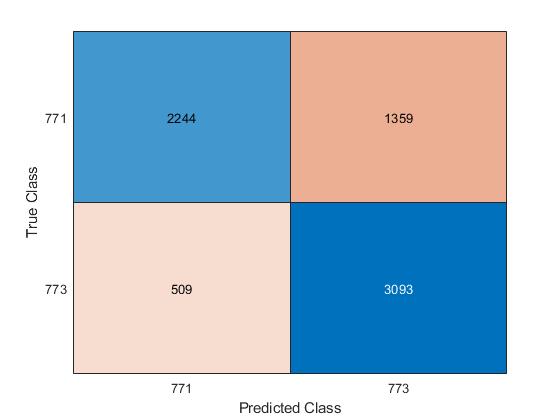

confusionchart(label_train, predicted_labels);

## test the model on online data

predicted_labels = predict(model, test_set);
accuracy = sum(label_test == predicted_labels)/length(label_test);

disp(["the accuracy on test set is " accuracy]);

    "the accuracy on test set is "    "0.70849"



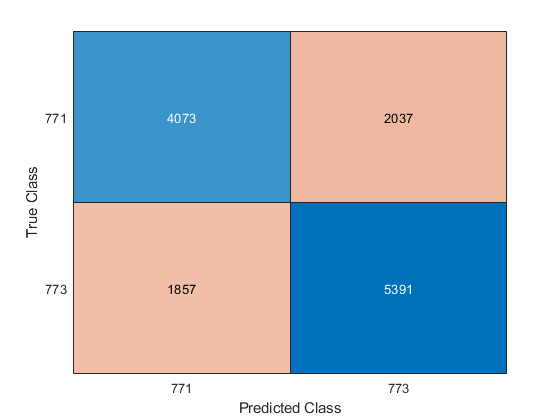

confusionchart(label_test, predicted_labels);